# Simple cells

Simple cells in V1 respond to bars of light at specific orientations and scales. One way to model these cells is with a Gabor function. 

## Build Gabor function

这里介绍gabor

clear all; clc;

#### 初始化OR和SF两个参数。

通过不同的OR和SF，构建不同的方向和空间频率敏感的simple cell

%% 2a Define values
OR = 0; %orientation in radians
SF = 0.01;  %spatial frequency

#### 进行二维坐标旋转变换

将原始的*(x,y)*坐标系绕原点以角度*θ* 逆时针旋转，得到新的坐标*(X,Y)。*

x = -20:1:20;
[x, y] = meshgrid(x);
X=x*cos(OR) + y*sin(OR);
Y=-x*sin(OR) + y*cos(OR);

#### 创建Gabor function

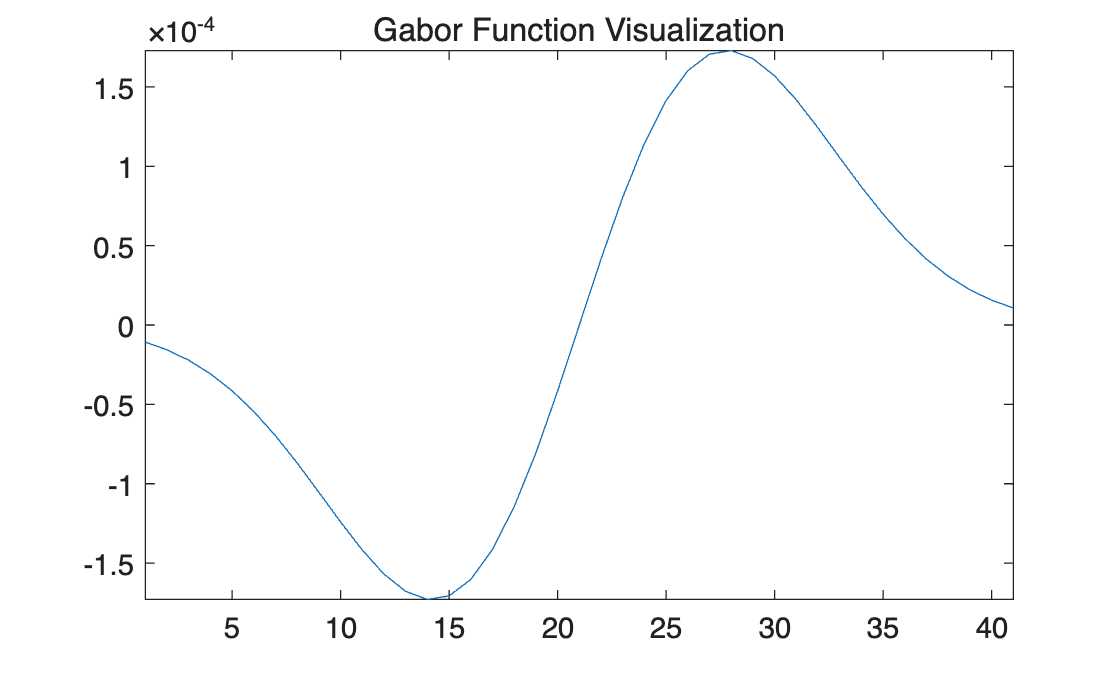

sigma_x = 7; % standard deviation in x-direction
sigma_y = 17; % standard deviation in y-direction

gaussian_2d = 1/(2*pi*sigma_x*sigma_y) * exp(-(X.^2/(2*sigma_x^2)+Y.^2/(2*sigma_y^2)));
A = sin(2*pi*SF*X);
Gabor_function = A .* gaussian_2d;

%plot figure
figure;
plot(Gabor_function(1,:));
axis tight;
title('Gabor Function Visualization');

## convolve image with Gabor function

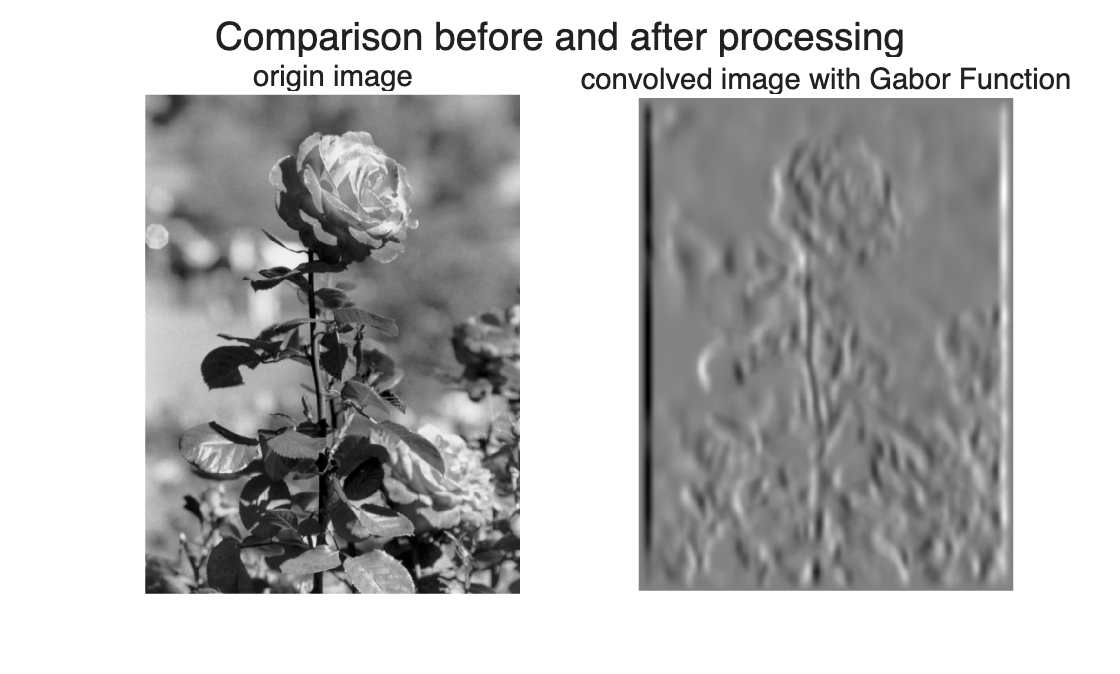

img = imread('rose.jpg');
img_conv = conv2(img, Gabor_function);

% Display the convolved image
figure;
subplot(1,2,1)
imshow(img)
title('origin image')
subplot(1,2,2)
imagesc(img_conv);
colormap(gray);
axis image;
axis off;
title('convolved image with Gabor Function');
sgtitle('Comparison before and after processing');

## 改变参数OR，对比区别

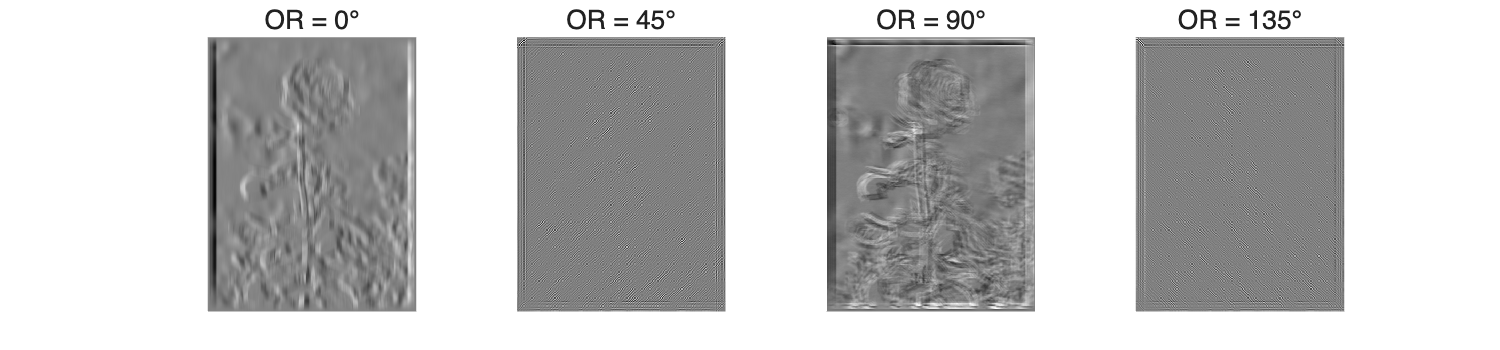

img = imread('rose.jpg');
SF = 0.5;
ORs = [0, pi/4, pi/2, 3*pi/4];
titles = {'0°', '45°', '90°', '135°'};
figure('Position', [100, 100, 1500, 350]);
for i = 1:4
    OR = ORs(i);
    X = x*cos(OR) + y*sin(OR);
    Y = -x*sin(OR) + y*cos(OR);

    gaussian_2d = 1/(2*pi*sigma_x*sigma_y) * exp(-(X.^2/(2*sigma_x^2)+Y.^2/(2*sigma_y^2)));
    A = sin(2*pi*SF*X);

    Gabor_function = A .* gaussian_2d;

    img_conv = conv2(img, Gabor_function);
    subplot(1,4,i)
    imagesc(img_conv);
    colormap(gray);
    axis image;
    axis off;
    title(['OR = ' titles{i}]);
end

这里可以发现，对于这个图片90°上的细节比较多。在空间频率比较大（比较精细）的细胞中，只有90°敏感的细胞提取到了更多的信息。

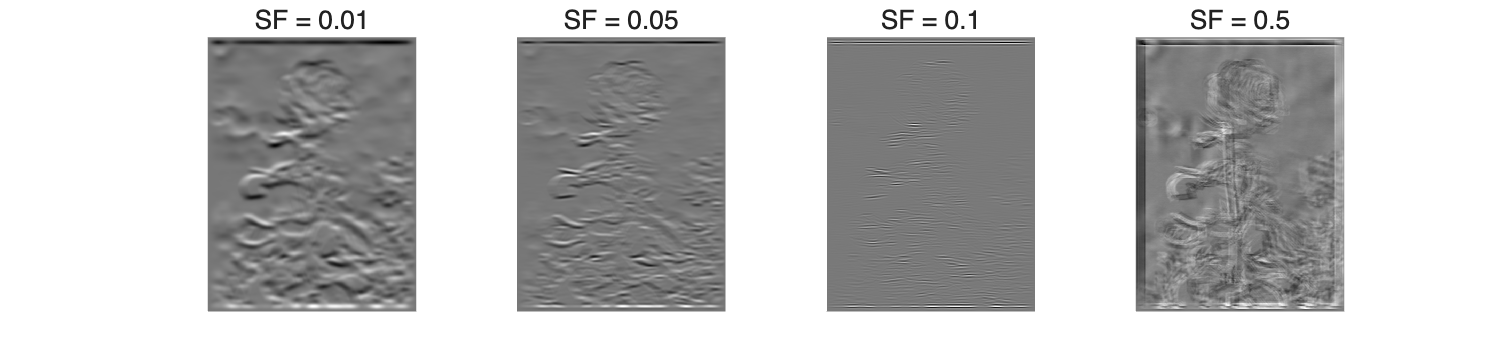

% sigma_x = 3; % standard deviation in x-direction
% sigma_y = 25; % standard deviation in y-direction
SFs = [0.01, 0.05, 0.1, 0.5];
titles = {'0.01', '0.05', '0.1', '0.5'};
OR = pi/2;
X = x*cos(OR) + y*sin(OR);
Y = -x*sin(OR) + y*cos(OR);
figure('Position', [100, 100, 1500, 350]);
for i = 1:4
    SF = SFs(i);
    gaussian_2d = 1/(2*pi*sigma_x*sigma_y) * exp(-(X.^2/(2*sigma_x^2)+Y.^2/(2*sigma_y^2)));
    A = sin(2*pi*SF*X);
    Gabor_function = A .* gaussian_2d;

    img_conv = conv2(img, Gabor_function);

    subplot(1,4,i)
    imagesc(img_conv);
    colormap(gray);
    axis image;
    axis off;
    title(['SF = ' titles{i}]);
end